# 3.24

The linear constant coefficient difference equation

**y[n] = 1/3{x[n] + x[n − 1] + x[n − 2]} + 0.95y[n − 1] − 0.9025y[n − 2]**

is excited by the input x[n] = cos(πn/3)u[n] subject to the initial conditions:

**y[−1] = −2, y[−2] = −3, x[−1] = 1, x[−2] = 1.**

(a) Determine analytically the complete response y[n].

(b) Verify your answer using MATLAB.

b = [1,1,1]/3; a = [1,-0.95,0.9025];
Y = [-2,-3]; X = [1,1]; 

xic=filtic(b,a,Y,X)

xic =     1.4742    2.1383


bxplus = [1,-0.5]; axplus = [1,-1,1]; % X(z) transform coeff.
ayplus = conv(a,axplus) % Denominator of Yplus(z)

ayplus =     1.0000   -1.9500    2.8525   -1.8525    0.9025


byplus = conv(b,bxplus)+conv(xic,axplus) % Numerator of Yplus(z)

byplus =     1.8075    0.8308   -0.4975    1.9717


[R,p,C] = residuez(byplus,ayplus)

R =    0.0584 - 3.9468i
   0.0584 + 3.9468i
   0.8453 + 2.0311i
   0.8453 - 2.0311i


p =    0.5000 + 0.8660i
   0.5000 - 0.8660i
   0.4750 + 0.8227i
   0.4750 - 0.8227i



C =

     []



Mp = abs(p), Ap = angle(p)/pi % Polar form

Mp =     1.0000
    1.0000
    0.9500
    0.9500


Ap =     0.3333
   -0.3333
    0.3333
   -0.3333


n = [0:10]; x = cos(pi*n/3); y = filter(b,a,x,xic)

y =     1.8075    4.3555    2.8398   -1.5664   -4.7176   -3.4014    1.3596    5.0281    3.8829   -1.1824   -5.2943



H = tf(b,a,1)

H =
 
  0.3333 z^2 + 0.3333 z + 0.3333
  ------------------------------
      z^2 - 0.95 z + 0.9025
 
Sample time: 1 seconds
Discrete-time transfer function.



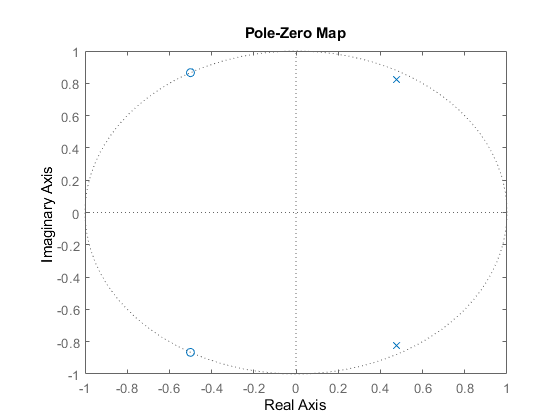

pzmap(H)